close all
clear all
clc 


Creating default tank object 

MainTank = gmt_Tank("MainTank")

MainTank =   gmt_Tank with properties:

                   Name: "MainTank"
             EdgeMatrix: [4×2 double]
                  Edges: [1×4 gmt_Edge]
               Vertices: [1×6 gmt_Vertex]
             Properties: [1×1 gmtProp.gmt_Properties]
                DiGraph: [1×1 digraph]
                 Inputs: ["u1"    "u2"]
              InputData: [1×2 gmt_Input]
                 States: ["x1"    "x2"]
                Outputs: [0×1 string]
           Disturbances: "x4"
           Optimization: [0×0 string]
        ModelParameters: [1×1 gmt_Parameter]
        SystemEquations: [1×1 struct]
    SystemEquationsSubs: [1×1 struct]
      InitialConditions: []
          ModelMetadata: [1×1 struct]
                  Ports: [1×2 gmt_Port]


Initial condition report

MainTank.gmt_ReportInitCon



Vertex Name              Vertex    Initial     State   
                         State    Condition   Variable 
                        Variable               Units   
______________________ _________ ___________ _________ 
MainTank: Temperature      x1     Unassigned     K     
MainTank: Mass             x2     Unassigned     kg    



 Add initial conditions after object is created

MainTank = MainTank.gmt_InitCon([300,6000])

MainTank =   gmt_Tank with properties:

                   Name: "MainTank"
             EdgeMatrix: [4×2 double]
                  Edges: [1×4 gmt_Edge]
               Vertices: [1×6 gmt_Vertex]
             Properties: [1×1 gmtProp.gmt_Properties]
                DiGraph: [1×1 digraph]
                 Inputs: ["u1"    "u2"]
              InputData: [1×2 gmt_Input]
                 States: ["x1"    "x2"]
                Outputs: [0×1 string]
           Disturbances: "x4"
           Optimization: [0×0 string]
        ModelParameters: [1×1 gmt_Parameter]
        SystemEquations: [1×1 struct]
    SystemEquationsSubs: [1×1 struct]
      InitialConditions: [300 6000]
          ModelMetadata: [1×1 struct]
                  Ports: [1×2 gmt_Port]


 Initial conditions during object creation  

clear MainTank 
MainTank = gmt_Tank("MainTank","InitCon",[300,6000])

MainTank =   gmt_Tank with properties:

                   Name: "MainTank"
             EdgeMatrix: [4×2 double]
                  Edges: [1×4 gmt_Edge]
               Vertices: [1×6 gmt_Vertex]
             Properties: [1×1 gmtProp.gmt_Properties]
                DiGraph: [1×1 digraph]
                 Inputs: ["u1"    "u2"]
              InputData: [1×2 gmt_Input]
                 States: ["x1"    "x2"]
                Outputs: [0×1 string]
           Disturbances: "x4"
           Optimization: [0×0 string]
        ModelParameters: [1×1 gmt_Parameter]
        SystemEquations: [1×1 struct]
    SystemEquationsSubs: [1×1 struct]
      InitialConditions: [300 6000]
          ModelMetadata: [1×1 struct]
                  Ports: [1×2 gmt_Port]


Full model report

MainTank.gmt_ReportFull


Graph Report


Vertex Name                          Vertex      Vertex    State   Capacitance  Capacitance  Capacitance     Power Equation                               
                                     Type        State    Variable Inputs                    Equation                                                     
                                                Variable   Units                                                                                          
____________________________________ _________ _________ _________ ____________ ____________ _______________ ____________________________________________ 
MainTank: Temperature                Internal      x1        K                  cp_f*x2      cp_f*x2*x1_dot  cp_f*u1*x4 - cp_f*u2*x1 - cp_f*x1*(u1 - u2)  
MainTank: Mass                       Internal      x2        kg                 1            x2_dot          u1 - u2                                      
MainTank: Mass Conservation          

 Plot graph for MainTank

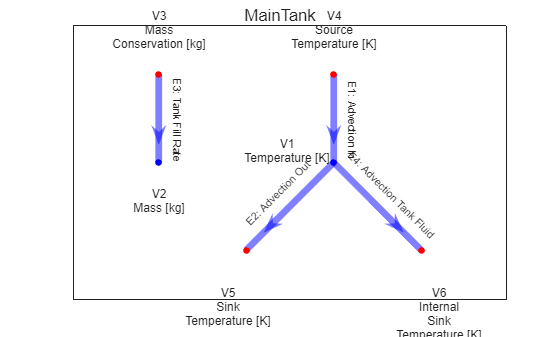

MainTank.gmt_PlotGraph

Build simulation for mainTank with initial conditions

pathName = "C:\Users\jmp8430\Documents\Research\GraphModel_ToolboxV2\doc";
MainTank = gmt_Tank("MainTank","BuildSim",pathName,"InitCon",[300,6000])

MainTank =   gmt_Tank with properties:

                   Name: "MainTank"
             EdgeMatrix: [4×2 double]
                  Edges: [1×4 gmt_Edge]
               Vertices: [1×6 gmt_Vertex]
             Properties: [1×1 gmtProp.gmt_Properties]
                DiGraph: [1×1 digraph]
                 Inputs: ["u1"    "u2"]
              InputData: [1×2 gmt_Input]
                 States: ["x1"    "x2"]
                Outputs: [0×1 string]
           Disturbances: "x4"
           Optimization: [0×0 string]
        ModelParameters: [1×1 gmt_Parameter]
        SystemEquations: [1×1 struct]
    SystemEquationsSubs: [1×1 struct]
      InitialConditions: [300 6000]
          ModelMetadata: [1×1 struct]
                  Ports: [1×2 gmt_Port]


**Demonstrate MATLAB simulation **

    -Show ODE function 

    -Run sim script 

**Demonstrate Simulink**

Model linearization 

Z is affine transformation to provide linear approximation of dynamics rather than deviation from linearization point

[A, B, Z] = MainTank.gmt_ControlModel

$$A(x1, x2, u1, u2) = \left(\begin{array}{cc} -\frac{{\mathrm{cp}}_{f}\,u_{2}+{\mathrm{cp}}_{f}\,\left(u_{1}-u_{2}\right)}{{\mathrm{cp}}_{f}\,x_{2}} & \frac{{\mathrm{cp}}_{f}\,u_{2}\,x_{1}-{\mathrm{cp}}_{f}\,u_{1}\,x_{4}+{\mathrm{cp}}_{f}\,x_{1}\,\left(u_{1}-u_{2}\right)}{{\mathrm{cp}}_{f}\,{x_{2}}^{2}}\\ 0 & 0 \end{array}\right)$$

$$B(x1, x2, u1, u2) = \left(\begin{array}{cc} -\frac{{\mathrm{cp}}_{f}\,x_{1}-{\mathrm{cp}}_{f}\,x_{4}}{{\mathrm{cp}}_{f}\,x_{2}} & 0\\ 1 & -1 \end{array}\right)$$

$$Z(x1, x2, u1, u2) = \left(\begin{array}{c} \frac{u_{1}\,\left({\mathrm{cp}}_{f}\,x_{1}-{\mathrm{cp}}_{f}\,x_{4}\right)}{{\mathrm{cp}}_{f}\,x_{2}}-\frac{2\,\left({\mathrm{cp}}_{f}\,u_{2}\,x_{1}-{\mathrm{cp}}_{f}\,u_{1}\,x_{4}+{\mathrm{cp}}_{f}\,x_{1}\,\left(u_{1}-u_{2}\right)\right)}{{\mathrm{cp}}_{f}\,x_{2}}+\frac{x_{1}\,\left({\mathrm{cp}}_{f}\,u_{2}+{\mathrm{cp}}_{f}\,\left(u_{1}-u_{2}\right)\right)}{{\mathrm{cp}}_{f}\,x_{2}}\\ 0 \end{array}\right)$$

Model linearization with simplified expression  

[A, B, Z] = MainTank.gmt_ControlModel("Simplify",true)

$$A(x1, x2, u1, u2) = \left(\begin{array}{cc} -\frac{u_{1}}{x_{2}} & \frac{u_{1}\,\left(x_{1}-x_{4}\right)}{{x_{2}}^{2}}\\ 0 & 0 \end{array}\right)$$

$$B(x1, x2, u1, u2) = \left(\begin{array}{cc} -\frac{x_{1}-x_{4}}{x_{2}} & 0\\ 1 & -1 \end{array}\right)$$

$$Z(x1, x2, u1, u2) = \left(\begin{array}{c} \frac{u_{1}\,x_{1}}{x_{2}}-\frac{{\mathrm{cp}}_{f}\,u_{2}\,x_{1}-{\mathrm{cp}}_{f}\,u_{1}\,x_{4}+{\mathrm{cp}}_{f}\,x_{1}\,\left(u_{1}-u_{2}\right)}{{\mathrm{cp}}_{f}\,x_{2}}\\ 0 \end{array}\right)$$

Model linearization with parameter value substitution  

[A, B, Z] = MainTank.gmt_ControlModel("NumSub",true)

$$A(x1, x2, u1, u2) = \left(\begin{array}{cc} -\frac{u_{1}}{x_{2}} & \frac{3300\,u_{2}\,x_{1}-3300\,u_{1}\,x_{4}+3300\,x_{1}\,\left(u_{1}-u_{2}\right)}{3300\,{x_{2}}^{2}}\\ 0 & 0 \end{array}\right)$$

$$B(x1, x2, u1, u2) = \left(\begin{array}{cc} -\frac{3300\,x_{1}-3300\,x_{4}}{3300\,x_{2}} & 0\\ 1 & -1 \end{array}\right)$$

$$Z(x1, x2, u1, u2) = \left(\begin{array}{c} \frac{u_{1}\,x_{1}}{x_{2}}-\frac{3300\,u_{2}\,x_{1}-3300\,u_{1}\,x_{4}+3300\,x_{1}\,\left(u_{1}-u_{2}\right)}{1650\,x_{2}}+\frac{u_{1}\,\left(3300\,x_{1}-3300\,x_{4}\right)}{3300\,x_{2}}\\ 0 \end{array}\right)$$

System of equations without parameter value substitution  

 MainTank.SystemEquations.Expression

$$ans = \left(\begin{array}{c} x_{\dot{1}}=-\frac{{\mathrm{cp}}_{f}\,u_{2}\,x_{1}-{\mathrm{cp}}_{f}\,u_{1}\,x_{4}+{\mathrm{cp}}_{f}\,x_{1}\,\left(u_{1}-u_{2}\right)}{{\mathrm{cp}}_{f}\,x_{2}}\\ x_{\dot{2}}=u_{1}-u_{2} \end{array}\right)$$

System of equations with parameter value substitution  

MainTank.SystemEquationsSubs.Expression

$$ans = \left(\begin{array}{c} x_{\dot{1}}=-\frac{3300\,u_{2}\,x_{1}-3300\,u_{1}\,x_{4}+3300\,x_{1}\,\left(u_{1}-u_{2}\right)}{3300\,x_{2}}\\ x_{\dot{2}}=u_{1}-u_{2} \end{array}\right)$$

**Creating a system model based on Doman dual tank model [1]**

[1] D. B. Doman, “Fuel flow control for extending aircraft thermal endurance part I: underlying principles,” in AIAA SciTech 2016 Forum, (San Diego, CA, USA) Jan. 2016

Section: Component model connections and input matching

clearvars -except pathName
close all
clc

tic

% Define Each Componnet
HeatLoad = gmt_HeatLoad("HeatLoad");
CoolerLoad = gmt_HeatLoad("CoolerLoad");
MainTank = gmt_Tank("MainTank");
RecirTank = gmt_Tank("RecirTank");
EngineSplit = gmt_SplitJunction("EngineSplit",1,2);
TankSplit = gmt_SplitJunction("TankSplit",2,1);

% Combine Each Component 
% Primary object equations take priority 
PrimaryObj = ...
    {MainTank; 
     RecirTank; 
     RecirTank; 
     CoolerLoad; 
     EngineSplit; 
     HeatLoad};

SecondaryObj = ...
    {TankSplit; 
     TankSplit; 
     CoolerLoad; 
     EngineSplit; 
     HeatLoad; 
     TankSplit};

ObjectArray = {PrimaryObj,SecondaryObj};

PortArray = ...
    [2, 1; 
     2, 2; 
     1, 2; 
     1, 2; 
     1, 2; 
     1, 3];

% Call static method gmt_Combine
FuelSystem = gmt_Graph.gmt_Combine("FuelSystem",ObjectArray,PortArray);
toc

Elapsed time is 0.823132 seconds.


Inputs dependency are not automated in the toolbox for complexity reasons 

Additional step to assign input dependency

FuelSystem.gmt_ReportInput



 Variable Parent       Description          Units 
_________ ____________ ___________________ ______ 
    u1    CoolerLoad   Inlet Mass Flow 1    kg/s  
    u2    EngineSplit  Inlet Mass Flow 1    kg/s  
    u4    EngineSplit  Outlet Mass Flow 2   kg/s  
    u5    HeatLoad     Inlet Mass Flow 1    kg/s  
    u6    MainTank     Inlet Mass Flow 1    kg/s  
    u7    MainTank     Outlet Mass Flow 1   kg/s  
    u8    RecirTank    Inlet Mass Flow 1    kg/s  
    u9    RecirTank    Outlet Mass Flow 1   kg/s  



Match dependent inputs within system model, applying conversion of mass

InputMatching = ...
[ "u2", "(u7+u9)"; ...
  "u5", "(u7+u9)"; ...
  "u1", "u8"; ...
  "u4", "(u7+u9-u8)"];

% Update Model W/ Matched Inputs
% call method from object 
FuelSystem = FuelSystem.gmt_InputCommon(InputMatching)

FuelSystem =   gmt_Graph with properties:

                   Name: "FuelSystem"
             EdgeMatrix: [14×2 double]
                  Edges: [1×14 gmt_Edge]
               Vertices: [1×16 gmt_Vertex]
             Properties: [1×1 gmtProp.gmt_Properties]
                DiGraph: [1×1 digraph]
                 Inputs: ["u6"    "u7"    "u8"    "u9"]
              InputData: [1×4 gmt_Input]
                 States: ["x1"    "x3"    "x5"    "x7"    "x8"    "x12"    "x13"    "x16"]
                Outputs: [0×1 string]
           Disturbances: ["x2"    "x6"    "x10"]
           Optimization: [0×0 string]
        ModelParameters: [1×6 gmt_Parameter]
        SystemEquations: [1×1 struct]
    SystemEquationsSubs: [1×1 struct]
      InitialConditions: []
          ModelMetadata: [1×1 struct]
                  Ports: [1×7 gmt_Port]


% system graph model report 
FuelSystem.gmt_ReportFull


Graph Report


Vertex Name                              Vertex      Vertex    State   Capacitance  Capacitance     Capacitance Equation    Power Equation                                           
                                         Type        State    Variable Inputs                                                                                                        
                                                    Variable   Units                                                                                                                 
________________________________________ _________ _________ _________ ____________ _______________ _______________________ ________________________________________________________ 
CoolerLoad: Fluid Temperature            Internal      x1        K                  cp_f*V_1*rho_f  V_1*cp_f*rho_f*x1_dot   x2 - cp_f*u8*x1 + cp_f*u8*x3                             
CoolerLoad: Energy Applied               External      x2

% system model initial conditions
FuelSystem.gmt_ReportInitCon



Vertex Name                                Vertex    Initial     State   
                                           State    Condition   Variable 
                                          Variable               Units   
________________________________________ _________ ___________ _________ 
CoolerLoad: Fluid Temperature                x1     Unassigned     K     
EngineSplit: Junction Fluid Temperature      x3     Unassigned     K     
HeatLoad: Fluid Temperature                  x5     Unassigned     K     
MainTank: Temperature                        x7     Unassigned     K     
MainTank: Mass                               x8     Unassigned     kg    
RecirTank: Temperature                      x12     Unassigned     K     
RecirTank: Mass                             x13     Unassigned     kg    
TankSplit: Junction Fluid Temperature       x16     Unassigned     K     



% update initial conditions
FuelSystem = FuelSystem.gmt_InitCon([300,300,300,300,6000,300,1500,300])

FuelSystem =   gmt_Graph with properties:

                   Name: "FuelSystem"
             EdgeMatrix: [14×2 double]
                  Edges: [1×14 gmt_Edge]
               Vertices: [1×16 gmt_Vertex]
             Properties: [1×1 gmtProp.gmt_Properties]
                DiGraph: [1×1 digraph]
                 Inputs: ["u6"    "u7"    "u8"    "u9"]
              InputData: [1×4 gmt_Input]
                 States: ["x1"    "x3"    "x5"    "x7"    "x8"    "x12"    "x13"    "x16"]
                Outputs: [0×1 string]
           Disturbances: ["x2"    "x6"    "x10"]
           Optimization: [0×0 string]
        ModelParameters: [1×6 gmt_Parameter]
        SystemEquations: [1×1 struct]
    SystemEquationsSubs: [1×1 struct]
      InitialConditions: [300 300 300 300 6000 300 1500 300]
          ModelMetadata: [1×1 struct]
                  Ports: [1×7 gmt_Port]


Build system model simulation

FuelSystem = FuelSystem.gmt_BuildSim(pathName)

FuelSystem =   gmt_Graph with properties:

                   Name: "FuelSystem"
             EdgeMatrix: [14×2 double]
                  Edges: [1×14 gmt_Edge]
               Vertices: [1×16 gmt_Vertex]
             Properties: [1×1 gmtProp.gmt_Properties]
                DiGraph: [1×1 digraph]
                 Inputs: ["u6"    "u7"    "u8"    "u9"]
              InputData: [1×4 gmt_Input]
                 States: ["x1"    "x3"    "x5"    "x7"    "x8"    "x12"    "x13"    "x16"]
                Outputs: [0×1 string]
           Disturbances: ["x2"    "x6"    "x10"]
           Optimization: [0×0 string]
        ModelParameters: [1×6 gmt_Parameter]
        SystemEquations: [1×1 struct]
    SystemEquationsSubs: [1×1 struct]
      InitialConditions: [300 300 300 300 6000 300 1500 300]
          ModelMetadata: [1×1 struct]
                  Ports: [1×7 gmt_Port]


**Demonstration Fuel System Model**

System of equations without parameter value substitution  

FuelSystem.SystemEquations.Expression

$$ans = \begin{array}{l} \left(\begin{array}{c} x_{\dot{1}}=\frac{x_{2}-{\mathrm{cp}}_{f}\,u_{8}\,x_{1}+{\mathrm{cp}}_{f}\,u_{8}\,x_{3}}{V_{1}\,{\mathrm{cp}}_{f}\,\rho_{f}}\\ x_{\dot{3}}=-\frac{{\mathrm{cp}}_{f}\,x_{3}\,\left(u_{7}-u_{8}+u_{9}\right)-\sigma_{2}+{\mathrm{cp}}_{f}\,u_{8}\,x_{3}}{V_{2}\,{\mathrm{cp}}_{f}\,\rho_{f}}\\ x_{\dot{5}}=\frac{x_{6}-\sigma_{2}+\sigma_{1}}{V_{3}\,{\mathrm{cp}}_{f}\,\rho_{f}}\\ x_{\dot{7}}=-\frac{{\mathrm{cp}}_{f}\,u_{7}\,x_{7}-{\mathrm{cp}}_{f}\,u_{6}\,x_{10}+{\mathrm{cp}}_{f}\,x_{7}\,\left(u_{6}-u_{7}\right)}{{\mathrm{cp}}_{f}\,x_{8}}\\ x_{\dot{8}}=u_{6}-u_{7}\\ x_{\dot{12}}=-\frac{{\mathrm{cp}}_{f}\,u_{9}\,x_{12}-{\mathrm{cp}}_{f}\,u_{8}\,x_{1}+{\mathrm{cp}}_{f}\,x_{12}\,\left(u_{8}-u_{9}\right)}{{\mathrm{cp}}_{f}\,x_{13}}\\ x_{\dot{13}}=u_{8}-u_{9}\\ x_{\dot{16}}=\frac{{\mathrm{cp}}_{f}\,u_{7}\,x_{7}-\sigma_{1}+{\mathrm{cp}}_{f}\,u_{9}\,x_{12}}{V_{4}\,{\mathrm{cp}}_{f}\,\rho_{f}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{cp}}_{f}\,x_{16}\,\left(u_{7}+u_{9}\right)\\ \sigma_{2}={\mathrm{cp}}_{f}\,x_{5}\,\left(u_{7}+u_{9}\right) \end{array}$$

Linearized model with parameter value substitution  

[As, Bs, Zs] = FuelSystem.gmt_ControlModel("NumSub",true)

$$As(x1, x3, x5, x7, x8, x12, x13, x16, u6, u7, u8, u9) = \begin{array}{l} \left(\begin{array}{cccccccc} -\frac{50\,u_{8}}{109} & \frac{50\,u_{8}}{109} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & \sigma_{1} & \sigma_{2} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \sigma_{1} & 0 & 0 & 0 & 0 & \sigma_{2}\\ 0 & 0 & 0 & -\frac{u_{6}}{x_{8}} & \frac{3300\,u_{7}\,x_{7}-3300\,u_{6}\,x_{10}+3300\,x_{7}\,\left(u_{6}-u_{7}\right)}{3300\,{x_{8}}^{2}} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ \frac{u_{8}}{x_{13}} & 0 & 0 & 0 & 0 & -\frac{u_{8}}{x_{13}} & \frac{3300\,u_{9}\,x_{12}-3300\,u_{8}\,x_{1}+3300\,x_{12}\,\left(u_{8}-u_{9}\right)}{3300\,{x_{13}}^{2}} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{50\,u_{7}}{109} & 0 & \frac{50\,u_{9}}{109} & 0 & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{50\,u_{7}}{109}-\frac{50\,u_{9}}{109}\\ \sigma_{2}=\frac{50\,u_{7}}{109}+\frac{50\,u_{9}}{109} \end{array}$$

$$Bs(x1, x3, x5, x7, x8, x12, x13, x16, u6, u7, u8, u9) = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & \frac{50\,x_{3}}{109}-\frac{50\,x_{1}}{109} & 0\\ 0 & \sigma_{2} & 0 & \sigma_{2}\\ 0 & \sigma_{1} & 0 & \sigma_{1}\\ -\frac{3300\,x_{7}-3300\,x_{10}}{3300\,x_{8}} & 0 & 0 & 0\\ 1 & -1 & 0 & 0\\ 0 & 0 & \frac{3300\,x_{1}-3300\,x_{12}}{3300\,x_{13}} & 0\\ 0 & 0 & 1 & -1\\ 0 & \frac{50\,x_{7}}{109}-\frac{50\,x_{16}}{109} & 0 & \frac{50\,x_{12}}{109}-\frac{50\,x_{16}}{109} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{50\,x_{16}}{109}-\frac{50\,x_{5}}{109}\\ \sigma_{2}=\frac{50\,x_{5}}{109}-\frac{50\,x_{3}}{109} \end{array}$$

$$Zs(x1, x3, x5, x7, x8, x12, x13, x16, u6, u7, u8, u9) = \begin{array}{l} \left(\begin{array}{c} \frac{x_{2}}{7194}+u_{8}\,\left(\frac{50\,x_{1}}{109}-\frac{50\,x_{3}}{109}\right)\\ \sigma_{5}-\frac{50\,u_{8}\,x_{3}}{109}+x_{3}\,\sigma_{1}-x_{5}\,\sigma_{1}+u_{7}\,\sigma_{3}+u_{9}\,\sigma_{3}-\frac{50\,x_{3}\,\left(u_{7}-u_{8}+u_{9}\right)}{109}\\ \frac{x_{6}}{7194}-\sigma_{5}+\sigma_{4}+x_{5}\,\sigma_{1}-x_{16}\,\sigma_{1}+u_{7}\,\sigma_{2}+u_{9}\,\sigma_{2}\\ \frac{u_{6}\,x_{7}}{x_{8}}-\frac{3300\,u_{7}\,x_{7}-3300\,u_{6}\,x_{10}+3300\,x_{7}\,\left(u_{6}-u_{7}\right)}{1650\,x_{8}}+\frac{u_{6}\,\left(3300\,x_{7}-3300\,x_{10}\right)}{3300\,x_{8}}\\ 0\\ \frac{u_{8}\,x_{12}}{x_{13}}-\frac{u_{8}\,x_{1}}{x_{13}}-\frac{3300\,u_{9}\,x_{12}-3300\,u_{8}\,x_{1}+3300\,x_{12}\,\left(u_{8}-u_{9}\right)}{1650\,x_{13}}-\frac{u_{8}\,\left(3300\,x_{1}-3300\,x_{12}\right)}{3300\,x_{13}}\\ 0\\ x_{16}\,\sigma_{1}-\sigma_{4}-u_{7}\,\left(\frac{50\,x_{7}}{109}-\frac{50\,x_{16}}{109}\right)-u_{9}\,\left(\frac{50\,x_{12}}{109}-\frac{50\,x_{16}}{109}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{50\,u_{7}}{109}+\frac{50\,u_{9}}{109}\\ \sigma_{2}=\frac{50\,x_{5}}{109}-\frac{50\,x_{16}}{109}\\ \sigma_{3}=\frac{50\,x_{3}}{109}-\frac{50\,x_{5}}{109}\\ \sigma_{4}=\frac{50\,x_{16}\,\left(u_{7}+u_{9}\right)}{109}\\ \sigma_{5}=\frac{50\,x_{5}\,\left(u_{7}+u_{9}\right)}{109} \end{array}$$